# Maze Solving Using Q-learning Algorithm

**Author:** Bhartendu Thakur, Viji Narayan

**School:** Departement of Mathematics, IIST

## Description

In this example we will sovle a maze using Q-Learning (Reinforcement Learning)

**Reinforcement Learning**

Reinforcement learning (Sutton & Barto, 1998) is a principled mathematical framework for experience-driven, goal-directed learning and decision making. RL starts with interaction between agent and environment, agent take action in environment, which drives it to next state and receives a rewards based on the goodness of that action. As shown in figure 1, at any time-step ***t***, agent being in state $s_t$ take action $a_t$ in environment gets reward $r_t$ and observe next state $s_{t+1}$. Reinforcement learning algorithms, push up the probabilities of taking good actions to achieve desired goals. In this example we'll solve *n x n *maze using Q-learning technique.

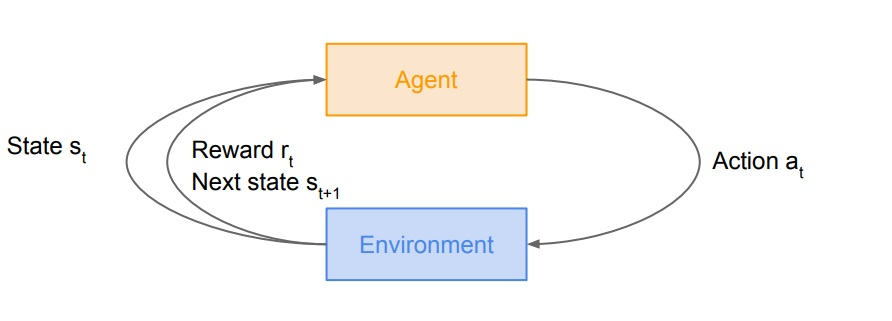

 FIGURE 1: Reinforcement Learning

**Q-Learning**

Reinforcement learning can generally be sub-divided into model-free & model-based as shown in figure 2. In model-based RL dynamical model of the environment is used & in model-free RL, a policy or value function is learnt.

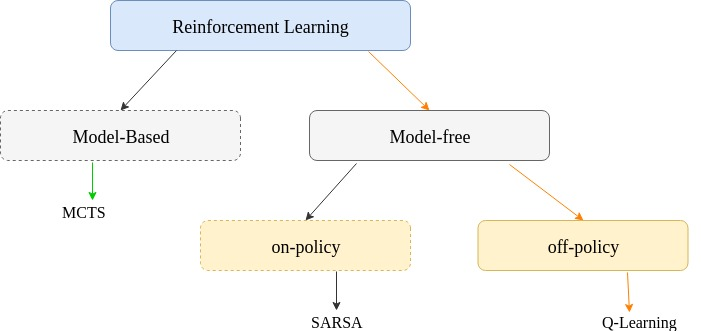

FIGURE 2: Subdivision in RL

Model-free RL is divided into two broad categories, off-policy & on-policy learning. On-policy method such as SARSA, return for state-action pairs assuming the current policy continues to be followed is estimated, where return is termed for total discounted future reward. In off-policy methods policy used to generate training data (Behaviour policy) & policy to be estimated (Target policy) are different.

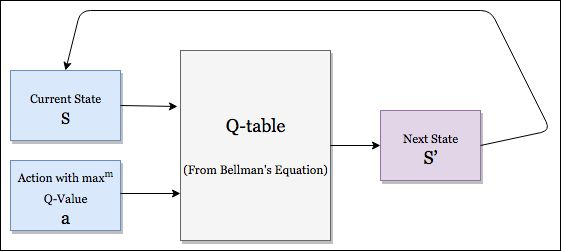

FIGURE 3: Block diagram: Q-learning

Q-learning as shown in figure 2, a model-free, off-policy learning proposed by (Watkins & Dayan, 1992) is basically process of evaluating the goodness of a state-action pair. Q-value at state* s* and action *a*, is defined the expected cumulative reward from taking action *a* in state* s* and then following the *policy. *In other words Q-Learning is off-policy learning as one can choose our action just by looking at $Q(s', a')$, without worrying about what happens next. In each episode, Q-values of current state *s* are updated using the Q-value of next state *s'* and the greedy action *a'* using Bellman Optimality Equation which is given below,


$$Q^*(s,a) = \mathbb{E}_{s' \sim \epsilon}\bigg[{ r + \gamma \max_{a'} Q^*(s', a') \Big| s, a }\bigg]$$


**Bellman Equation** for Q-value Function serves as a target (greedy) policy along with   $\epsilon$-greedy policy as behavior policy where random action is chosen with a small probability of $\epsilon$, greedy action with probability of (1 -  $\epsilon$). Decaying  $\epsilon$, with time another kind of behavior policy.

## Let's create a maze

- Size of maze denoted by n

n = 12;

- Randomly Generating Path/Links

maze = -50*ones(n,n);

for i=1:(n-3)*n
    maze(randi([1,n]),randi([1,n]))=1;
end

- Starting Node

maze(1,1) = 1;

- Goal

maze(n,n) = 10;

*For a stored solvable maze uncomment following:*

% load('maze12x12.mat');

Display maze in matrix form is:

disp(maze)

     1     1   -50   -50     1     1     1   -50     1   -50   -50   -50
   -50   -50   -50     1     1   -50   -50     1     1     1     1     1
     1   -50   -50   -50   -50     1     1     1     1   -50     1   -50
     1     1     1   -50     1     1   -50     1     1   -50     1     1
   -50   -50     1   -50     1   -50   -50   -50     1   -50   -50   -50
     1   -50   -50     1     1     1     1     1   -50     1     1   -50
   -50     1     1   -50   -50     1     1     1     1     1   -50   -50
     1     1   -50     1   -50   -50   -50   -50   -50   -50     1     1
     1   -50     1     1   -50   -50   -50     1     1   -50     1   -50
   -50     1     1     1   -50     1   -50   -50     1   -50   -50   -50
     1     1     1   -50     1     1   -50   -50     1   -50     1     1
   -50     1     1     1     1   -50   -50     1     1     1     1    10



## Visualizing the MAZE

- Check for atleast one path between Start & Goal

- Dimension of maze 12x12 i.e., n=12

- Starting Position is (1,1)

- Goal is to reach (12,12)

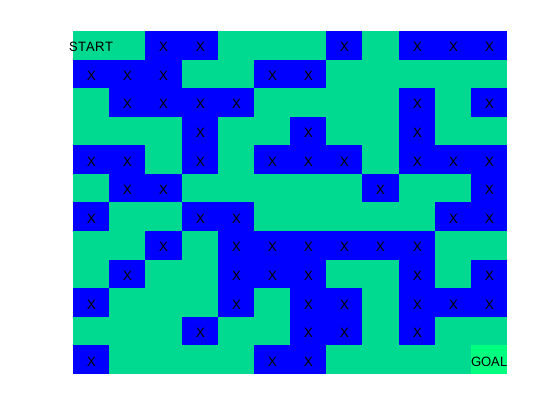

n=length(maze);

figure
imagesc(maze)
colormap(winter)

for i=1:n
    for j=1:n
        if maze(i,j)==min(maze)
            text(j,i,'X','HorizontalAlignment','center')
        end
    end
end
text(1,1,'START','HorizontalAlignment','center')
text(n,n,'GOAL','HorizontalAlignment','center')

axis off


Goal=n*n;
fprintf('Goal State is: %d',Goal)

Goal State is: 144

## Creating Reward Matrix for the Maze

Possible actions are:

- Up      :  (i-n)

- Down :  (i+n)

- Left    :  (i-1)

- Right  :  (i+1)

- Diagonally SE  :  (i+n+1)

- Diagonally SW :  (i+n-1)

- Diagonally NE  :  (i-n+1)

- Diagonally NW :  (i-n-1)

Reward  is - $\infty$ (i.e. No reward) for any other actions. Thus any other action other then above action will not occur.

reward=zeros(n*n);

for i=1:Goal
    reward(i,:)=reshape(maze',1,Goal);
end

for i=1:Goal
    for j=1:Goal
        if j~=i-n  && j~=i+n  && j~=i-1 && j~=i+1 && j~=i+n+1 && j~=i+n-1 && j~=i-n+1 && j~=i-n-1
            reward(i,j)=-Inf;
        end    
    end
end

for i=1:n:Goal
    for j=1:i+n
        if j==i+n-1 || j==i-1 || j==i-n-1
            reward(i,j)=-Inf;
            reward(j,i)=-Inf;
        end
    end
end

## Q-Learning algorithm

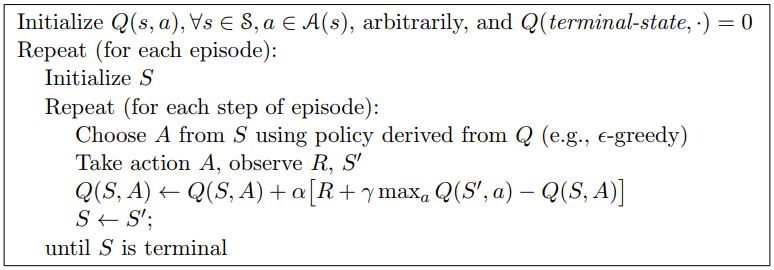

FIGURE 4: Q-learning: An off-policy TD control algorithm [(Refer to Reinforcement Learning: An Introduction)](http://web.stanford.edu/class/psych209/Readings/SuttonBartoIPRLBook2ndEd.pdf)

In this chunk we,

- Initialize the Q-matrix.

- Set the goal state to be 'n*n'. 

- Set Discount factor $\gamma =0\ldotp 9$ [(Influence of variables on the algorithm)](https://ipfs.io/ipfs/QmXoypizjW3WknFiJnKLwHCnL72vedxjQkDDP1mXWo6uco/wiki/Q-Learning.html)

- Learning rate, $\alpha =0\ldotp 2$ (Selected after several runs)

- Set maximum number of iterations

q = randn(size(reward));
gamma = 0.9;
alpha = 0.2;
maxItr = 50;

- cs $\Rightarrow$ current state

- ns $\Rightarrow$ next state

*Repeat until Convergence OR Maximum Iterations*

for i=1:maxItr
    
    % Starting from start position    
    cs=1;
    
    % Repeat until Goal state is reached
    while(1)
        
    % possible actions for the chosen state
    n_actions = find(reward(cs,:)>0);

    % choose an action at random and set it as the next state
    ns = n_actions(randi([1 length(n_actions)],1,1));
       
            % find all the possible actions for the selected state
            n_actions = find(reward(ns,:)>=0);
            
            % find the maximum q-value i.e, next state with best action
            max_q = 0;
            for j=1:length(n_actions)
                max_q = max(max_q,q(ns,n_actions(j)));
            end
            
            % Update q-values as per Bellman's equation
            q(cs,ns)=reward(cs,ns)+gamma*max_q;
            
            % Check whether the episode has completed i.e Goal has been reached
            if(cs == Goal)
                break;
            end
            
            % Set current state as next state
            cs=ns;
    end
end

## Solving the maze

- Starting from the first postion

start = 1;
move = 0;
path = start;

- Iterating until Goal-State is reached

while(move~=Goal)
    [~,move]=max(q(start,:));
    
    % Deleting chances of getting stuck in small loops  (upto order of 4)  
    if ismember(move,path)
        [~,x]=sort(q(start,:),'descend');
        move=x(2); 
        if ismember(move,path)
            [~,x]=sort(q(start,:),'descend');
            move=x(3);
            if ismember(move,path)
                [~,x]=sort(q(start,:),'descend');
                move=x(4);
                if ismember(move,path)
                    [~,x]=sort(q(start,:),'descend');
                    move=x(5);
                end
            end
        end
    end
    
    % Appending next action/move to the path
    path=[path,move];
    start=move;
end

## Solution of maze 

i.e, Optimal Path between START to GOAL

fprintf('Final path: %s',num2str(path))

Final path: 1   14   27   16   17   30   43   55   68   81   93  106  119  132  144

fprintf('Total steps: %d',length(path))

Total steps: 15

% reproducing path to matrix path
pmat=zeros(n,n);

[q, r]=quorem(sym(path),sym(n));
q=double(q);r=double(r);
q(r~=0)=q(r~=0)+1;r(r==0)=n;

for i=1:length(q)
    pmat(q(i),r(i))=50;
end  

## Final Plot of the maze

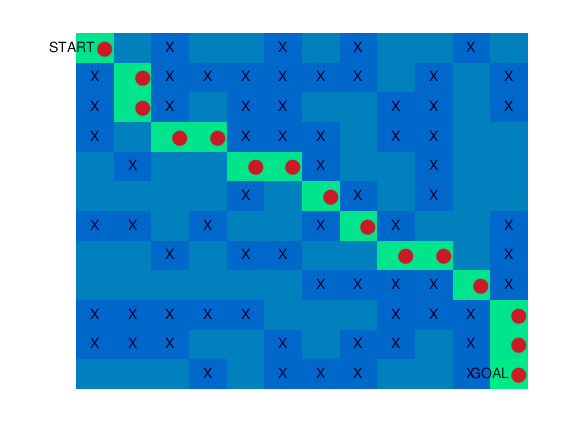

figure
imagesc(pmat)
colormap(white)

for i=1:n
    for j=1:n
        if maze(i,j)==min(maze)
            text(j,i,'X','HorizontalAlignment','center')
        end
        if pmat(i,j)==50
            text(j,i,'\bullet','Color','red','FontSize',28)
        end
    end
end
text(1,1,'START','HorizontalAlignment','right')
text(n,n,'GOAL','HorizontalAlignment','right')

hold on
imagesc(maze,'AlphaData',0.2)
colormap(winter)
hold off
axis off

## Thus, we solved the maze and optimal path has been shown.

 - Bhartendu, Machine Learning & Computing, [[1]](https://www.linkedin.com/in/matrixb/) [[2]](https://in.mathworks.com/matlabcentral/profile/authors/10083740-bhartendu) [[3]](https://github.com/matrixbt)